# Sensing System - Proof of Concept

## Assumptions/Settings

Chirp Parameters:

- cycle period: 50 us

- idle time: 30 us

- slope: 1 MHz/us

- BW: 20 MHz

- SDR sampling rate: 50 Msps

"Spectogram Settings"

- fft size: 32 bin

- frequency sampling period: 1us (sampled every us)

## Constructing the Chirp

%configure chirp parameters
chirp_params.cycle_period_us = 50;
chirp_params.slope_MHz_us = 1;
chirp_params.BW_MHz = 20;
chirp_params.FMCW_sample_rate_Msps = 50;
chirp_params.ramp_end_time_us = chirp_params.BW_MHz / chirp_params.slope_MHz_us;
chirp_params.idle_time_us = chirp_params.cycle_period_us - chirp_params.ramp_end_time_us;
chirp_params.num_samples_idle_time = chirp_params.idle_time_us * chirp_params.FMCW_sample_rate_Msps;

%configure frame parameters
frame_params.num_chirps = 32;

%configure waveform parameters
waveform_params.sample_rate_Hz = chirp_params.FMCW_sample_rate_Msps * 1e6;
waveform_params.sweep_time_s = chirp_params.ramp_end_time_us * 1e-6;
waveform_params.sweep_BW_Hz = chirp_params.BW_MHz * 1e6;
waveform_params.sweep_interval = 'Positive';
waveform_params.sweep_direction = 'Up';
waveform_params.output_format = 'Sweeps';
waveform_params.num_sweeps = 1;

waveform = phased.FMCWWaveform("SampleRate",waveform_params.sample_rate_Hz, ...
                                'SweepTime', waveform_params.sweep_time_s, ...
                                'SweepBandwidth', waveform_params.sweep_BW_Hz, ...
                                'SweepDirection', waveform_params.sweep_direction, ...
                                'SweepInterval', waveform_params.sweep_interval, ...
                                'OutputFormat',waveform_params.output_format, ...
                                'NumSweeps',waveform_params.num_sweeps);

chirp = [zeros(chirp_params.num_samples_idle_time,1); waveform()];

## Generate a Spectogram

Steps to generate spectoram:

- reshape into 1us wide windows to sample frequency at (ex: 50 samples per 1us when sampling at 50 Msps)

- reduce the number of samples in the window to the desired size of fft (ex: 32 bits)

- window the sample signal

- perform fft

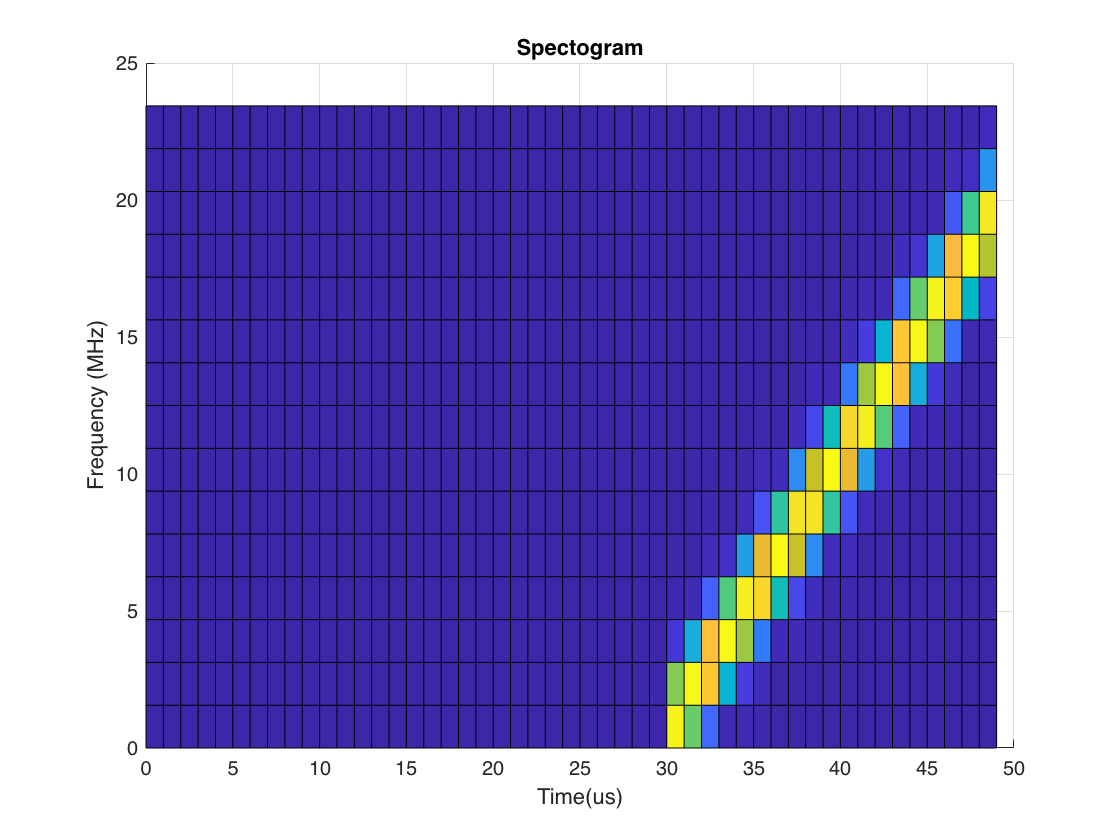

spectogram_params.fft_size = 32;
%for use in the simulink model
fft_size = 32;
spectogram_params.freq_sampling_period_us = 1; %sample frequency every 1us
spectogram_params.num_samples_per_sampling_window = spectogram_params.freq_sampling_period_us * chirp_params.FMCW_sample_rate_Msps;

%compute the window to be used when generating the spectogram
window = hann(spectogram_params.fft_size);

%first reshape the array into the desired window sizes
%chirp = [1:500].';
reshaped_signal = reshape(chirp,50,[]);

%next, shave off the last few samples so that we get the desired fft size
reshaped_signal_for_fft = reshaped_signal(1:spectogram_params.fft_size,:);

%window the signal
windowed_signal = reshaped_signal_for_fft .* window;

%perform an fft
generated_spectogram = fft(windowed_signal);

%clip off the negative frequencies;
generated_spectogram = generated_spectogram(1:spectogram_params.fft_size/2,:);
half_fft_size = spectogram_params.fft_size/2;

%plot the spectogram to confirm correct implementation
plot_params.max_freq = chirp_params.FMCW_sample_rate_Msps/2;
plot_params.freq_resolution = chirp_params.FMCW_sample_rate_Msps/spectogram_params.fft_size;
plot_params.frequencies = 0:plot_params.freq_resolution:plot_params.max_freq - plot_params.freq_resolution;
plot_params.times = 0: spectogram_params.freq_sampling_period_us : chirp_params.cycle_period_us - spectogram_params.freq_sampling_period_us;


%imagesc(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
surf(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
title_str = sprintf('Spectogram');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])

## Detect Peaks or CFAR to detect the points in the Spectogram

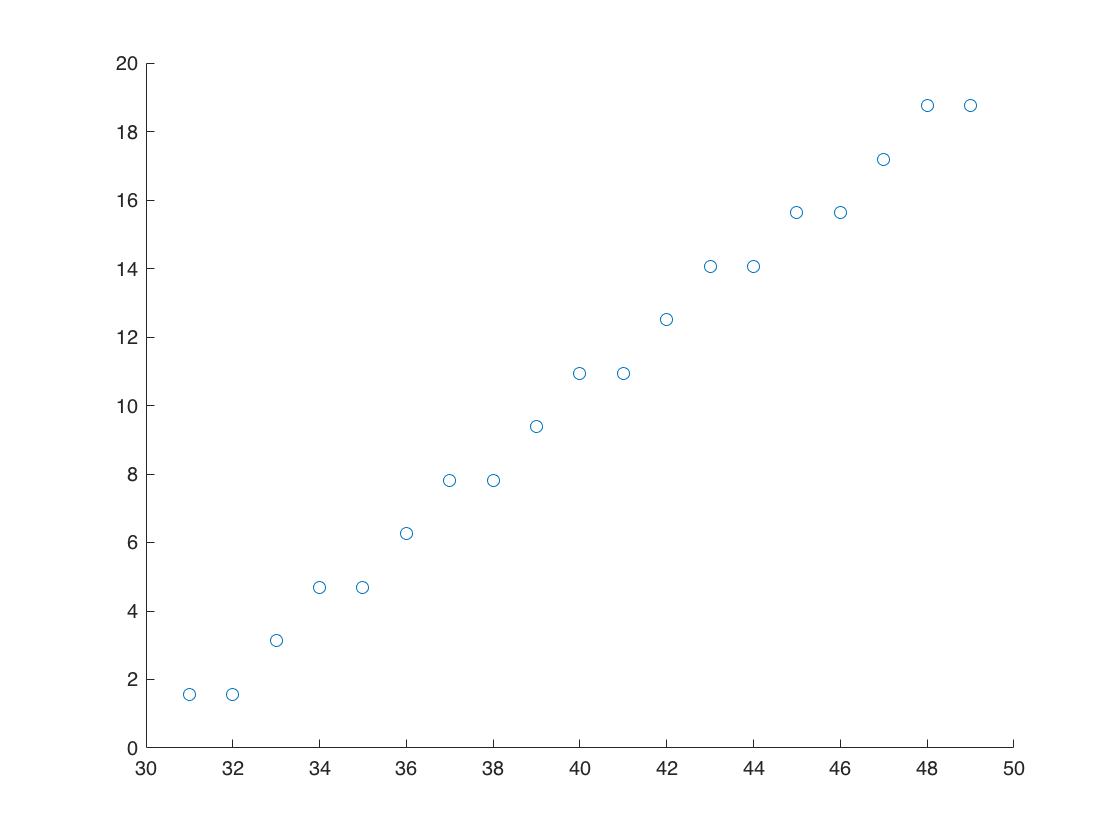

peak_detection_params.threshold = 5;
spectogram_points = [];  %array to hold the time, freq locations of valid spectogram points

for i = 1:size(generated_spectogram,2)
    [peaks,locations] = findpeaks(abs(generated_spectogram(:,i)));
    locations = locations(peaks > peak_detection_params.threshold);
    if ~isempty(locations)
        locations = [locations.'; i * ones(1,size(locations,1))];
        spectogram_points = [spectogram_points,locations];
    end
end

%plot the detected points to confirm that they align
detected_frequencies = plot_params.frequencies(spectogram_points(1,:));
detected_times = plot_params.times(spectogram_points(2,:));
scatter(detected_times,detected_frequencies);

## Fit a linear model to the computed points to determine slope and intercept

#### Initial Linear Model Computation

linear_model = fitlm(detected_times(1:16),detected_frequencies(1:16));
model_coefficients = table2array(linear_model.Coefficients(:,"Estimate"));
slope = model_coefficients(2)

slope = 1.0110

intercept = -model_coefficients(1)/model_coefficients(2)

intercept = 29.8068

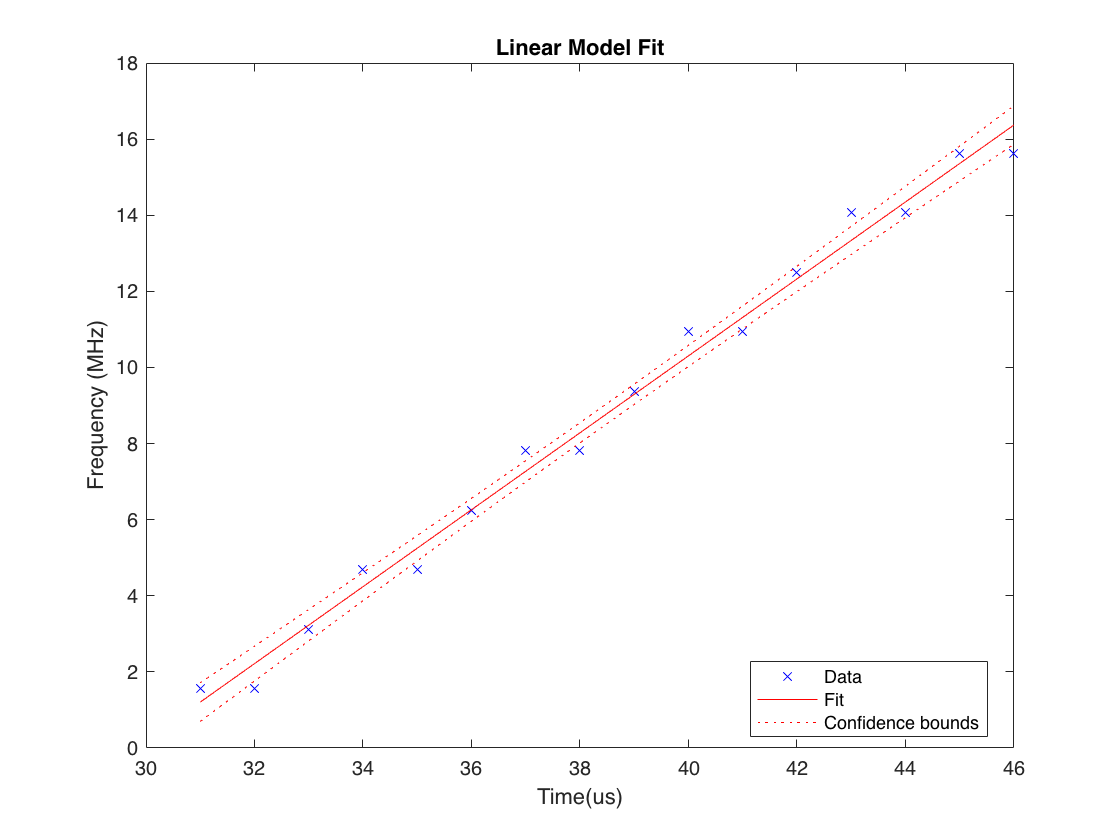

plot(linear_model)
title_str = sprintf('Linear Model Fit');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')

#### Revised Linear Model Computation:

link to resourse used to compute linear model: [https://online.stat.psu.edu/stat462/node/132/](https://online.stat.psu.edu/stat462/node/132/) 

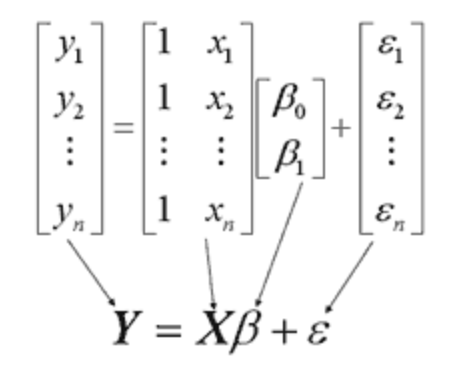

solving for this with out the Epsilon term though


$$\beta = (X^{T}X)^{-1}X^{T}Y$$


%solve for linear model using linear algrebra
%y is frequencies, x is time
X = [ones(size(detected_times,2),1),detected_times.'];
Y = detected_frequencies.';
B = inv(X.' * X) * X.' * Y;
slope = B(2);
intercept = -1 * B(1);

%values are the same

#### Simplified Linear Model

In order to implement this on physical hardware, I also wanted to experiment with implementing using the same number of points and to see how this affects the accuracy

%Now, we experiment with only taking 15 points to determine the slope and
%intercept
num_points_for_linearizing = 15;
X_simplified = [ones(num_points_for_linearizing,1),detected_times(1:num_points_for_linearizing).'];
Y_simplified = detected_frequencies(1:num_points_for_linearizing).';
B_simplified = inv(X_simplified.' * X_simplified) * X_simplified.' * Y_simplified;
slope_simplified = B_simplified(2);
intercept_simplified = -1 * B_simplified(1);

B_simplified - B

ans =    -1.0446
    0.0291


%shows that decreasing the number of points affected the computed intercept
%point

## Check simulated values to make sure that they are the same as matlab computed values

### Initialize the Simulink model and run it

open_system('SensingSubsystem');
set_param('SensingSubsystem','StopTime','5 * chirp_params.cycle_period_us * 1e-6')
out = sim('SensingSubsystem','SimulationMode','normal','SaveOutput','on');

### Reshaped Signal

%check a few chirps later to ensure that no timing errors or drift
reshaped_signal_simulink = out.reshaped_signal(:,:,5);
compare = all(reshaped_signal == reshaped_signal_simulink,'all');

if compare
    fprintf("Reshaped Signal: \t\t Matches")
else
    fprintf("Reshaped Signal: \t\t Does Not Match")
end

Reshaped Signal: 		 Matches

### Reshaped Signal - for fft

reshaped_signal_for_fft_simulink = out.reshaped_signal_for_fft(:,:,5);
compare = all(reshaped_signal_for_fft == reshaped_signal_for_fft_simulink,'all');

if compare
    fprintf("Reshaped Signal for fft: \t Matches")
else
    fprintf("Reshaped Signal for fft: \t Does Not Match")
end

Reshaped Signal for fft: 	 Matches

### Windowed Signal

windowed_signal_simulink = out.windowed_signal(:,:,5);
compare = all(windowed_signal == windowed_signal_simulink);
if compare
    fprintf("Windowed Signal: \t Matches")
else
    fprintf("Windowed Signal: \t Does Not Match")
end

Windowed Signal: 	 Matches

### Generated Spectogram

generated_spectogram_simulink = out.generated_spectogram(:,:,5);
compare = all(generated_spectogram == generated_spectogram_simulink);
if compare
    fprintf("Generated Spectogram: \t Matches")
else
    fprintf("Generated Spectogram: \t Does Not Match")
end

Generated Spectogram: 	 Matches

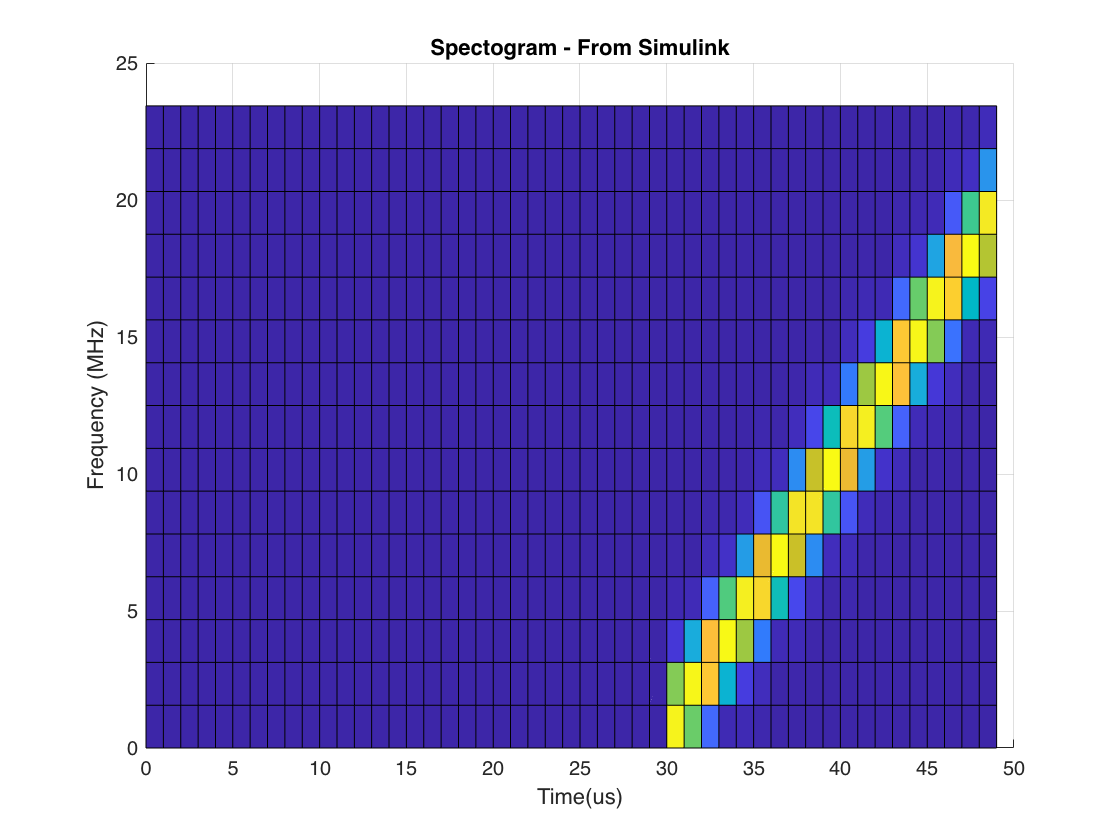

%imagesc(plot_params.times,plot_params.frequencies, abs(generated_spectogram));
surf(plot_params.times,plot_params.frequencies, abs(generated_spectogram_simulink));
title_str = sprintf('Spectogram - From Simulink');
title(title_str);
xlabel('Time(us)')
ylabel('Frequency (MHz)')
view([0,90.0])

### Detect Peaks

%obtain the detected times and frequencies
detected_times_simulink = out.detected_times(5,:);
detected_frequencies_simulink = out.detected_frequencies(5,:);

%clip the detections that aren't zero
detected_times_simulink = detected_times_simulink(detected_times_simulink > 0);
detected_frequencies_simulink = detected_frequencies_simulink(detected_frequencies_simulink > 0);

%compare times and frequencies
compare = all(detected_times_simulink == detected_times);
if compare
    fprintf("Detected Times: \t Matches")
else
    fprintf("Detected Times: \t Does Not Match")
end

Detected Times: 	 Matches


compare = all(detected_frequencies_simulink == detected_frequencies);
if compare
    fprintf("Detected Frequencies: \t Matches")
else
    fprintf("Detected Frequencies: \t Does Not Match")
end

Detected Frequencies: 	 Matches

### Verifing computed chirp and frame parameter calculations

slope_simulink = out.slope(5);
intercept_simulink = out.intercept(5);

compare = (slope_simulink - slope) < 1e-10;
if compare
    fprintf("Slope: \t Matches")
else
    fprintf("Slope: \t Does Not Match")
end

Slope: 	 Matches

compare = (intercept_simulink - intercept) < 1e-10;
if compare
    fprintf("Intercept: \t Matches")
else
    fprintf("Intercept: \t Does Not Match")
end

Intercept: 	 Matches

### Results of Simulation

%average slope
average_slope = out.chirp_memory(1,3,5)

average_slope = 1.0033

average_chirp_cycle_time = out.chirp_memory(1,6,5)

average_chirp_cycle_time = 50